# Generating Hand-drawn Digits Using Conditional Variational Autoencoder

clc, clear, close; % initializaiton

## Preparation of training images

Use Digits dataset prepared by the MathWorks for training hand-drawn digits.

digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');

imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

split the dataset into two parts: training and validation.

[imdsTrain, imdsValidation] = splitEachLabel(imds, 0.8, 'randomized');


Read MNIST image data...
Number of images in the dataset:  60000 ...



Read MNIST label data...
Number of labels in the dataset:  60000 ...


classes = 10×1 の cell 配列
    {'0'}
    {'1'}
    {'2'}
    {'3'}
    {'4'}
    {'5'}
    {'6'}
    {'7'}
    {'8'}
    {'9'}


classNum = 10

numTrainImages = 60000


Read MNIST image data...
Number of images in the dataset:  10000 ...



Read MNIST label data...
Number of labels in the dataset:  10000 ...


classes = unique(imdsTrain.Labels)
classNum = length(classes)
numTrainImages = length(imdsTrain.Files)

## Building of the autoencoder network

The network consitsts of two parts as well as VAE: decoder and encoder. The difference from VAE is that is has an input of label to both decoder and encoder. The label infomation is formed as one-hot vector, then be input in the following manner.

Encoder: the last feature map is vectorized by fully connected layer. Then after, it is concatenated with the one-hot vector. The resulted vector becomes a latent vector after being processed by fully connected layer again.

Decoder: the latent vecor is concatenated with the one-hot vector.

latentDim = 20; % the length of the latent vector
imageSize = [28 28 1]; % input image size

% Encoder network1 (feature extraction part)
encoderLG1 = layerGraph([
    imageInputLayer(imageSize,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    fullyConnectedLayer(2 * latentDim, 'Name', 'fc_encoder')
    ]);

% Encoder network2 (after label concatenation)
encoderLG2 = layerGraph([
   imageInputLayer([1 1 2*latentDim + classNum],"Normalization", 'none', "Name", 'input_label')
   fullyConnectedLayer(2*latentDim, 'Name', 'fc_encoder')]);

% Decoder network
decoderLG = layerGraph([
    imageInputLayer([1 1 latentDim+classNum], "Normalization","none","Name",'input_decoder')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);

A custom training loop is needed, because random noise and label information must be added while training. For this, the both networks is converted into dlnetwork class.

encoderNet1 = dlnetwork(encoderLG1);
encoderNet2 = dlnetwork(encoderLG2);
decoderNet = dlnetwork(decoderLG);

## Training options

The option settings are similar to those of VAE.

executionEnvironment = "auto";
numEpochs = 500;
minibatchSize = 500;
lr = 1e-3;
numIterations = floor(numTrainImages/minibatchSize);
iteration = 0;

avgGradientsEncoder1 = [];
avgGradientsSquaredEncoder1 = [];
avgGradientsEncoder2 = [];
avgGradientsSquaredEncoder2 = [];
avgGradientsDecoder = [];
avgGradientsSquaredDecoder = [];

## Trianing

Trian the dlnetwork with a custom training loop.

In the loop, the following processes are executed sequentially.

- preparation of minibatch data

- conversion of minibatch data type into dlarray object.

- (if available, conversion of dlarray object to gpuArray object)

- with modelGradients and dlfeval functions, loss and gradients are calculated.

- train the network with the adamupdate function

Epoch : 1 Test ELBO loss = 21.8766. Time taken for epoch = 11.0343s


Epoch : 2 Test ELBO loss = 20.9776. Time taken for epoch = 10.9324s


Epoch : 3 Test ELBO loss = 20.8409. Time taken for epoch = 10.8881s


Epoch : 4 Test ELBO loss = 20.7107. Time taken for epoch = 10.9741s


Epoch : 5 Test ELBO loss = 20.6644. Time taken for epoch = 10.9026s


Epoch : 6 Test ELBO loss = 20.542. Time taken for epoch = 10.8869s


Epoch : 7 Test ELBO loss = 20.4516. Time taken for epoch = 10.8817s


Epoch : 8 Test ELBO loss = 20.419. Time taken for epoch = 10.8773s


Epoch : 9 Test ELBO loss = 20.4205. Time taken for epoch = 10.9099s


Epoch : 10 Test ELBO loss = 20.2128. Time taken for epoch = 10.8778s


Epoch : 11 Test ELBO loss = 20.131. Time taken for epoch = 10.8812s


Epoch : 12 Test ELBO loss = 20.0429. Time taken for epoch = 10.9804s


Epoch : 13 Test ELBO loss = 19.6948. Time taken for epoch = 10.9113s


Epoch : 14 Test ELBO loss = 19.5962. Time taken for epoch = 10.8588s


Epoch : 15 Test ELBO loss = 19.4539. Time taken for epoch = 10.8839s


Epoch : 16 Test ELBO loss = 19.3214. Time taken for epoch = 10.8748s


Epoch : 17 Test ELBO loss = 19.2442. Time taken for epoch = 10.9396s


Epoch : 18 Test ELBO loss = 19.3813. Time taken for epoch = 18.4155s


Epoch : 19 Test ELBO loss = 19.2637. Time taken for epoch = 11.2403s


Epoch : 20 Test ELBO loss = 19.2246. Time taken for epoch = 10.9939s


Epoch : 21 Test ELBO loss = 19.1024. Time taken for epoch = 10.9273s


Epoch : 22 Test ELBO loss = 19.1789. Time taken for epoch = 10.9905s


Epoch : 23 Test ELBO loss = 19.1068. Time taken for epoch = 10.9863s


Epoch : 24 Test ELBO loss = 19.0169. Time taken for epoch = 10.9016s


Epoch : 25 Test ELBO loss = 19.1812. Time taken for epoch = 10.8795s


Epoch : 26 Test ELBO loss = 18.9356. Time taken for epoch = 10.9414s


Epoch : 27 Test ELBO loss = 18.8826. Time taken for epoch = 10.958s


Epoch : 28 Test ELBO loss = 18.8798. Time taken for epoch = 10.8856s


Epoch : 29 Test ELBO loss = 18.9554. Time taken for epoch = 10.865s


Epoch : 30 Test ELBO loss = 19.0112. Time taken for epoch = 10.8715s


Epoch : 31 Test ELBO loss = 18.9692. Time taken for epoch = 10.9086s


Epoch : 32 Test ELBO loss = 18.8941. Time taken for epoch = 10.8923s


Epoch : 33 Test ELBO loss = 18.9824. Time taken for epoch = 10.8798s


Epoch : 34 Test ELBO loss = 18.9109. Time taken for epoch = 10.8791s


Epoch : 35 Test ELBO loss = 18.799. Time taken for epoch = 10.8748s


Epoch : 36 Test ELBO loss = 18.9316. Time taken for epoch = 10.9105s


Epoch : 37 Test ELBO loss = 18.9055. Time taken for epoch = 10.8858s


Epoch : 38 Test ELBO loss = 18.8657. Time taken for epoch = 10.8554s


Epoch : 39 Test ELBO loss = 18.8299. Time taken for epoch = 10.8837s


Epoch : 40 Test ELBO loss = 18.9609. Time taken for epoch = 10.8804s


Epoch : 41 Test ELBO loss = 19.0727. Time taken for epoch = 10.9132s


Epoch : 42 Test ELBO loss = 18.9578. Time taken for epoch = 10.8763s


Epoch : 43 Test ELBO loss = 18.796. Time taken for epoch = 10.902s


Epoch : 44 Test ELBO loss = 19.0088. Time taken for epoch = 10.8884s


Epoch : 45 Test ELBO loss = 18.9255. Time taken for epoch = 10.881s


Epoch : 46 Test ELBO loss = 18.9388. Time taken for epoch = 10.8935s


Epoch : 47 Test ELBO loss = 18.8467. Time taken for epoch = 10.8715s


Epoch : 48 Test ELBO loss = 18.7396. Time taken for epoch = 10.8707s


Epoch : 49 Test ELBO loss = 18.9645. Time taken for epoch = 10.8858s


Epoch : 50 Test ELBO loss = 18.8297. Time taken for epoch = 10.8856s


Epoch : 51 Test ELBO loss = 18.8665. Time taken for epoch = 10.8846s


Epoch : 52 Test ELBO loss = 18.8064. Time taken for epoch = 10.8887s


Epoch : 53 Test ELBO loss = 18.8316. Time taken for epoch = 10.8586s


Epoch : 54 Test ELBO loss = 18.7474. Time taken for epoch = 10.9117s


Epoch : 55 Test ELBO loss = 18.8369. Time taken for epoch = 10.9163s


Epoch : 56 Test ELBO loss = 18.9596. Time taken for epoch = 10.9881s


Epoch : 57 Test ELBO loss = 18.8218. Time taken for epoch = 21.5448s


Epoch : 58 Test ELBO loss = 18.774. Time taken for epoch = 11.3423s


Epoch : 59 Test ELBO loss = 18.8617. Time taken for epoch = 11.9113s


Epoch : 60 Test ELBO loss = 18.8916. Time taken for epoch = 12.9757s


Epoch : 61 Test ELBO loss = 18.9198. Time taken for epoch = 12.8536s


Epoch : 62 Test ELBO loss = 18.7761. Time taken for epoch = 12.8356s


Epoch : 63 Test ELBO loss = 18.7722. Time taken for epoch = 12.7933s


Epoch : 64 Test ELBO loss = 18.8622. Time taken for epoch = 12.7196s


Epoch : 65 Test ELBO loss = 18.7725. Time taken for epoch = 12.8004s


Epoch : 66 Test ELBO loss = 18.8887. Time taken for epoch = 13.0382s


Epoch : 67 Test ELBO loss = 18.834. Time taken for epoch = 12.7694s


Epoch : 68 Test ELBO loss = 18.6433. Time taken for epoch = 12.713s


Epoch : 69 Test ELBO loss = 18.7862. Time taken for epoch = 12.7802s


Epoch : 70 Test ELBO loss = 18.9972. Time taken for epoch = 12.7864s


Epoch : 71 Test ELBO loss = 18.8119. Time taken for epoch = 12.7367s


Epoch : 72 Test ELBO loss = 18.8877. Time taken for epoch = 12.767s


Epoch : 73 Test ELBO loss = 18.7642. Time taken for epoch = 12.7432s


Epoch : 74 Test ELBO loss = 18.9219. Time taken for epoch = 12.7622s


Epoch : 75 Test ELBO loss = 18.8676. Time taken for epoch = 12.762s


Epoch : 76 Test ELBO loss = 18.8708. Time taken for epoch = 12.8387s


Epoch : 77 Test ELBO loss = 18.7327. Time taken for epoch = 12.7578s


Epoch : 78 Test ELBO loss = 18.8111. Time taken for epoch = 12.7636s


Epoch : 79 Test ELBO loss = 18.7858. Time taken for epoch = 12.7777s


Epoch : 80 Test ELBO loss = 18.7894. Time taken for epoch = 12.7747s


Epoch : 81 Test ELBO loss = 18.6876. Time taken for epoch = 12.7012s


Epoch : 82 Test ELBO loss = 18.8814. Time taken for epoch = 12.7743s


Epoch : 83 Test ELBO loss = 18.783. Time taken for epoch = 12.7203s


Epoch : 84 Test ELBO loss = 18.8047. Time taken for epoch = 12.8115s


Epoch : 85 Test ELBO loss = 18.8347. Time taken for epoch = 12.7905s


Epoch : 86 Test ELBO loss = 18.8369. Time taken for epoch = 12.7436s


Epoch : 87 Test ELBO loss = 18.8406. Time taken for epoch = 12.748s


Epoch : 88 Test ELBO loss = 18.7189. Time taken for epoch = 12.7183s


Epoch : 89 Test ELBO loss = 18.8138. Time taken for epoch = 12.7843s


Epoch : 90 Test ELBO loss = 18.8438. Time taken for epoch = 12.7361s


Epoch : 91 Test ELBO loss = 18.7896. Time taken for epoch = 12.7816s


Epoch : 92 Test ELBO loss = 18.7422. Time taken for epoch = 12.8508s


Epoch : 93 Test ELBO loss = 18.7852. Time taken for epoch = 12.7906s


Epoch : 94 Test ELBO loss = 18.7922. Time taken for epoch = 12.7546s


Epoch : 95 Test ELBO loss = 18.8009. Time taken for epoch = 12.7807s


Epoch : 96 Test ELBO loss = 18.8379. Time taken for epoch = 12.7966s


Epoch : 97 Test ELBO loss = 18.8327. Time taken for epoch = 12.7088s


Epoch : 98 Test ELBO loss = 18.7836. Time taken for epoch = 12.7012s


Epoch : 99 Test ELBO loss = 18.8566. Time taken for epoch = 12.8214s


Epoch : 100 Test ELBO loss = 18.6922. Time taken for epoch = 12.7416s


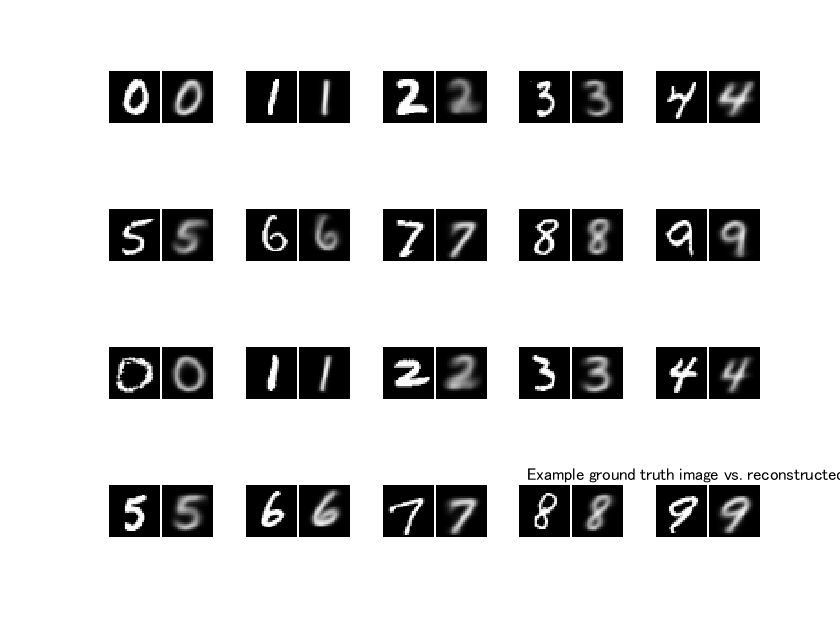

isTrain = true;
XTest = readall(imdsValidation);
XTest = dlarray(single(cat(4,XTest{:}))/255, 'SSCB');
YTest = full(ind2vec(double(imdsValidation.Labels)', classNum));
YTest = dlarray(single(reshape(YTest, [1,1,size(YTest)])), 'SSCB');

if isTrain
    for epoch=1:numEpochs
        tic;
        reset(imdsTrain);
        imdsTrain = shuffle(imdsTrain);
        for i=1:numIterations
            iteration = iteration + 1;
            idx = (i-1)*minibatchSize+1:i*minibatchSize;
            
            % preparation of minibatch data
            XBatch = read(imdsTrain);
            XBatch = dlarray(single(cat(4,XBatch{:}))/255, 'SSCB');
            YBatch = full(ind2vec(double(imdsTrain.Labels(idx))', classNum));
            YBatch = dlarray(single(reshape(YBatch, [1,1,size(YBatch)])), 'SSCB');
            
            if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
                XBatch = gpuArray(XBatch);           
            end 
                
            % calculation of loss and gradients
            [infGrad1, infGrad2, genGrad] = dlfeval(...
                @modelGradients, encoderNet1, encoderNet2, decoderNet, XBatch, YBatch);
            
            % train
            [decoderNet.Learnables, avgGradientsDecoder, avgGradientsSquaredDecoder] = ...
                adamupdate(decoderNet.Learnables, ...
                    genGrad, avgGradientsDecoder, avgGradientsSquaredDecoder, iteration, lr);
            [encoderNet1.Learnables, avgGradientsEncoder1, avgGradientsSquaredEncoder1] = ...
                adamupdate(encoderNet1.Learnables, ...
                    infGrad1, avgGradientsEncoder1, avgGradientsSquaredEncoder1, iteration, lr);
            [encoderNet2.Learnables, avgGradientsEncoder2, avgGradientsSquaredEncoder2] = ...
                adamupdate(encoderNet2.Learnables, ...
                    infGrad2, avgGradientsEncoder2, avgGradientsSquaredEncoder2, iteration, lr);
        end
        elapsedTime = toc;        
        
        if mod(epoch, 10) == 1 % loss calculation with validation data        
        [z, zMean, zLogvar] = sampling(encoderNet1, encoderNet2, XTest, YTest);
        z = cat(3, z, YTest);
        xPred = sigmoid(forward(decoderNet, z));
        elbo = ELBOloss(XTest, xPred, zMean, zLogvar);
        disp("Epoch : "+epoch+" Test ELBO loss = "+gather(extractdata(elbo))+...
            ". Time taken for epoch = "+ elapsedTime + "s") 
        end

        % smaller learning rate every 50 epoch 
        if mod(epoch, 50) == 0
            lr = lr * 0.5;
        end
        % generate images with current networks
        visualizeReconstruction(XTest, imdsValidation.Labels, encoderNet1, encoderNet2, decoderNet);
    end
    

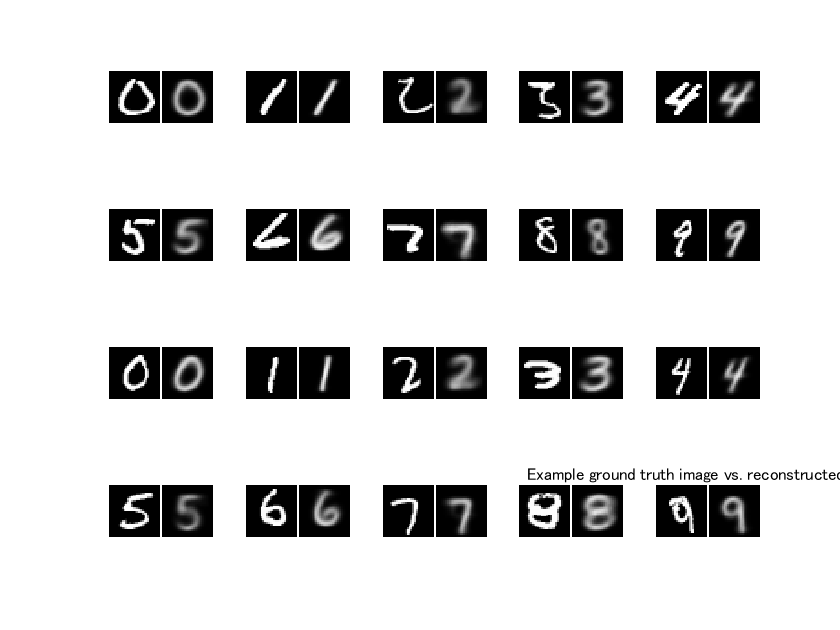

    % save the networks
    save Nets encoderNet1 encoderNet2 decoderNet;
else
    load Nets.mat 

end

## Visualization of the results

Let's reconstruct a image for every class.

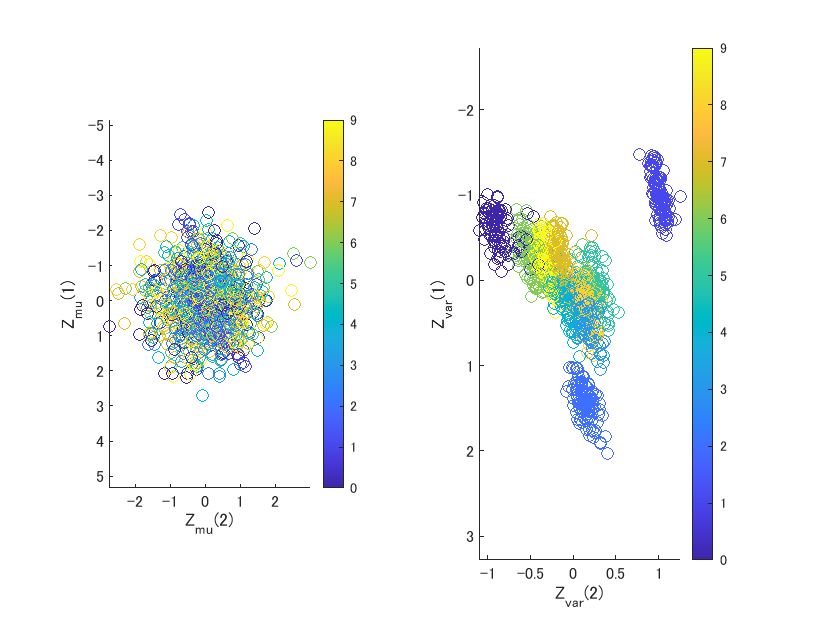

visualizeReconstruction(XTest, imdsValidation.Labels, encoderNet1, encoderNet2, decoderNet)

visualize the latent vector for every class.

visualizeLatentSpace(XTest, YTest, encoderNet1, encoderNet2)

Generate an arbitrary class image. Different imaeges are generated everytime you execute, because the latent vector is randomely picked. In addition, you can mix different classes by summing one-hot vectors.

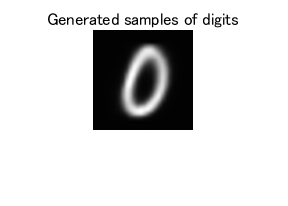

latentVec = randn(latentDim, 1); % random noise
classVec = zeros(classNum,1); % one-hot vector
classVec([1]) = 1; % 1 to 10 for 0 to 9 class,
figure,

generateSingleImage(decoderNet, latentVec, classVec)

Generate images of all classes with the common latent vector. See the feature of the generated images are similar. Here, five trials are executed by changing the latent vector.

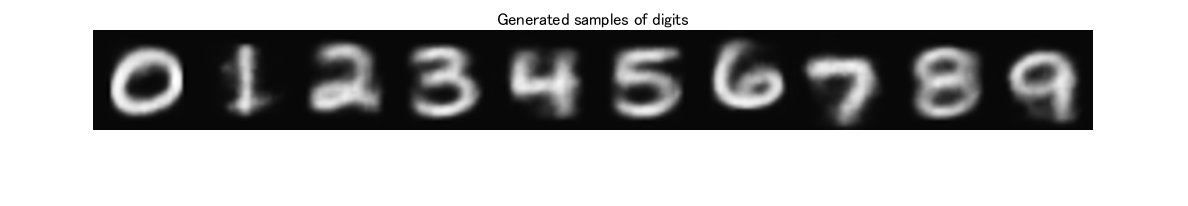

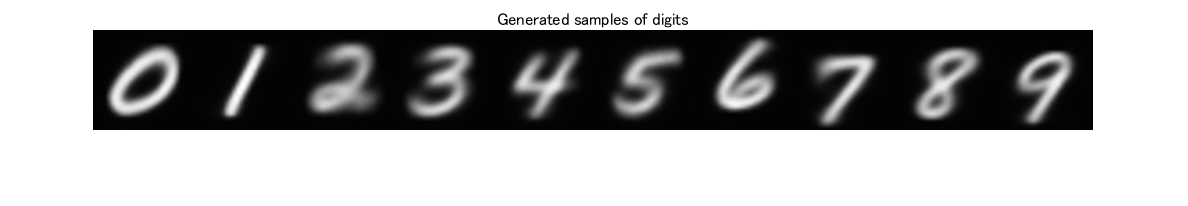

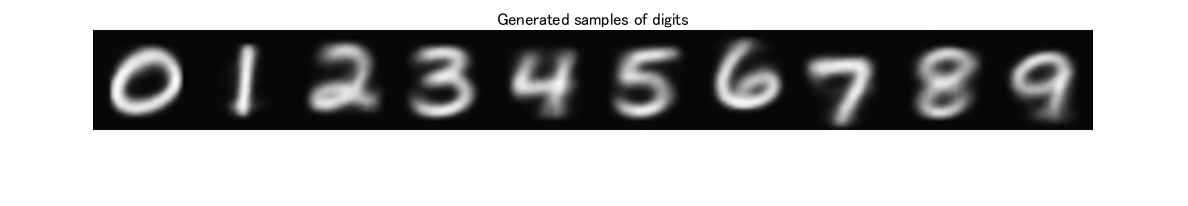

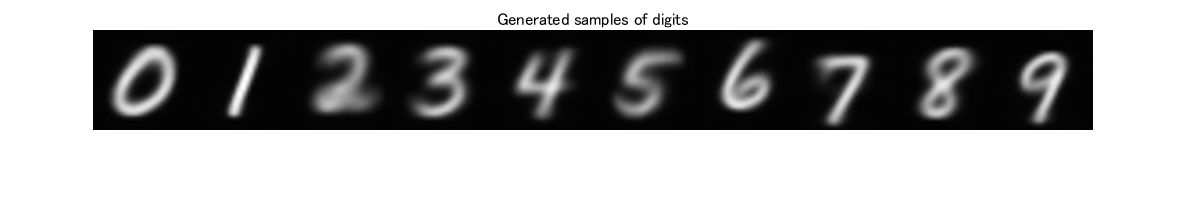

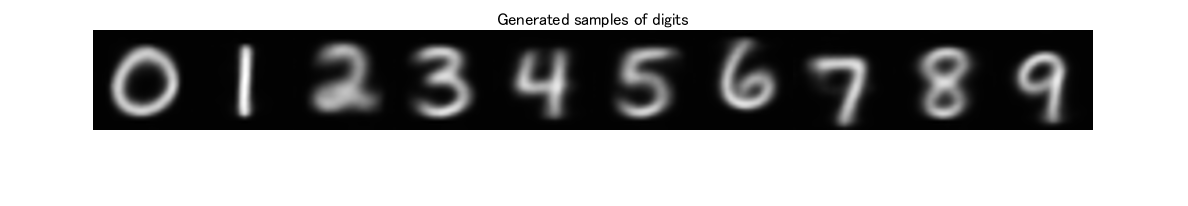

generate(decoderNet, latentDim, classNum)

## Supporting Functions

### Model Gradients Function

function [infGrad1, infGrad2, genGrad] = modelGradients(encoderNet1, encoderNet2, decoderNet, x, y)
    [z, zMean, zLogvar] = sampling(encoderNet1, encoderNet2, x, y); % Encoder
    z = cat(3, z, y); % the concatenation of feature vector with label vector
    xPred = sigmoid(forward(decoderNet, z));
    loss = ELBOloss(x, xPred, zMean, zLogvar);
    [genGrad, infGrad1, infGrad2] = dlgradient(loss, decoderNet.Learnables, ...
    encoderNet1.Learnables, encoderNet2.Learnables);
end

### Sampling and Loss Functions

function [z_sampled, zMean, zLogvar] = sampling(encoderNet1, encoderNet2, x, y)
temp = forward(encoderNet1, x);
temp = cat(3, temp, y); % the concatenation of feature vector with label vector
compressed = forward(encoderNet2, temp);
d = size(compressed,1)/2;
zMean = compressed(1:d,:);
zLogvar = compressed(1+d:end,:);

sz = size(zMean);
epsilon = randn(sz);
sigma = exp(.5 * zLogvar);
z = epsilon .* sigma + zMean;
z = reshape(z, [1,1,sz]);
z_sampled = dlarray(z, 'SSCB');
end

### `ELBOloss`

function elbo = ELBOloss(x, xPred, zMean, zLogvar)
squares = 0.5*(xPred-x).^2;
reconstructionLoss  = sum(squares, [1,2,3]);

KL = -.5 * sum(1 + zLogvar - zMean.^2 - exp(zLogvar), 1);

elbo = mean(reconstructionLoss + KL);
end

### Visualization Functions

function visualizeReconstruction(XTest,YTest, encoderNet1, encoderNet2, decoderNet)
for i = 1:2
    for c=0:9
        idx = iRandomIdxOfClass(YTest,c);
        X = dlarray(single(XTest(:,:,:,idx)), 'SSCB');
        Y = zeros(1,1,10,1);
        Y(uint8(YTest(idx))) = 1;
        Y = dlarray(single(Y), 'SSCB');

        [z, ~, ~] = sampling(encoderNet1, encoderNet2, X, Y);
        z = cat(3, z, Y);
        XPred = sigmoid(forward(decoderNet, z));
        
        X = gather(extractdata(X));
        XPred = gather(extractdata(XPred));

        comparison = [X, ones(size(X,1),1), XPred];
        subplot(4,5,(i-1)*10+c+1), imshow(comparison,[]),
    end
end
end

function idx = iRandomIdxOfClass(T,c)
idx = T == categorical(c);
idx = find(idx);
idx = idx(randi(numel(idx),1));
end

### Visualize Latent Space

function visualizeLatentSpace(XTest, YTest, encoderNet1, encoderNet2)
[~, zMean, zLogvar] = sampling(encoderNet1, encoderNet2, XTest, YTest);

zMean = stripdims(zMean)';
zMean = gather(extractdata(zMean));

zLogvar = stripdims(zLogvar)';
zLogvar = gather(extractdata(zLogvar));

[~,scoreMean] = pca(zMean);
[~,scoreLogvar] = pca(zLogvar);

c = parula(10);
f1 = figure;
figure(f1)
title("Latent space")

[maxv, maxi] = max(YTest, [], 3);
ah = subplot(1,2,1);
scatter(scoreMean(:,2),scoreMean(:,1),[],c(squeeze(uint8(extractdata(maxi))),:));
ah.YDir = 'reverse';
axis equal
xlabel("Z_m_u(2)")
ylabel("Z_m_u(1)")
cb = colorbar; cb.Ticks = 0:(1/9):1; cb.TickLabels = string(0:9);

ah = subplot(1,2,2);
scatter(scoreLogvar(:,2),scoreLogvar(:,1),[],c(squeeze(uint8(extractdata(maxi))),:));
ah.YDir = 'reverse';
xlabel("Z_v_a_r(2)")
ylabel("Z_v_a_r(1)")
cb = colorbar;  cb.Ticks = 0:(1/9):1; cb.TickLabels = string(0:9);
axis equal
end

### Generate images of all labels

function generate(decoderNet, latentDim, classNum)
drawNum = 5;
for drawi = 1:drawNum
    randomNoise = dlarray(repmat(randn(1,1,latentDim,1), [1 1 1 classNum]),'SSCB');
    labelarray = dlarray(single(reshape(full(ind2vec(double([1:classNum]), classNum)), [1 1 classNum classNum])), 'SSCB');
    generationSeed = cat(3, randomNoise, labelarray);
    generatedImage = sigmoid(predict(decoderNet, generationSeed));
    generatedImage = extractdata(generatedImage);
    
    f3 = figure;
    figure(f3)
    imshow(imtile(generatedImage, "ThumbnailSize", [100,100], "GridSize", [1 10]), [])
    title("Generated samples of digits")
    drawnow
end
end

Generate image of single class

function generateSingleImage(decoderNet, latentVec, classVec)
    randomNoise = dlarray(reshape(latentVec, 1, 1, [], 1),'SSCB');
    labelarray = dlarray(single(reshape(classVec, 1, 1, [], 1)), 'SSCB');
    generationSeed = cat(3, randomNoise, labelarray);
    generatedImage = sigmoid(predict(decoderNet, generationSeed));
    generatedImage = extractdata(generatedImage);
    
    imshow(imresize(generatedImage, [100 100]), []);
    title("Generated samples of digits")
end

*Copyright 2020 The MathWorks, Inc.*